clc
clear

%LOAD DATA
current_path = pwd;
path2dwt = fullfile(current_path, "Data_Covid", "train_dwt2twice");
imds = imageDatastore(path2dwt, 'IncludeSubfolders', true,...
    'LabelSource', 'foldernames', 'FileExtensions', '.mat', 'ReadFcn', @loadPD);

%SPLIT DATA
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.8);

%RESIZE IMAGES
std_size = [256, 256];
imdsTrainM = transform(imdsTrain,@(x1,x2) imresizePD(x1, x2, std_size),'IncludeInfo',true);
imdsValidationM = transform(imdsValidation,@(x1, x2) imresizePD(x1, x2, std_size),'IncludeInfo',true);

%
%lgraph = googlenetPD([256,256, 1], 4);
lgraph = xceptionPD([256,256, 1], 4);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 2).


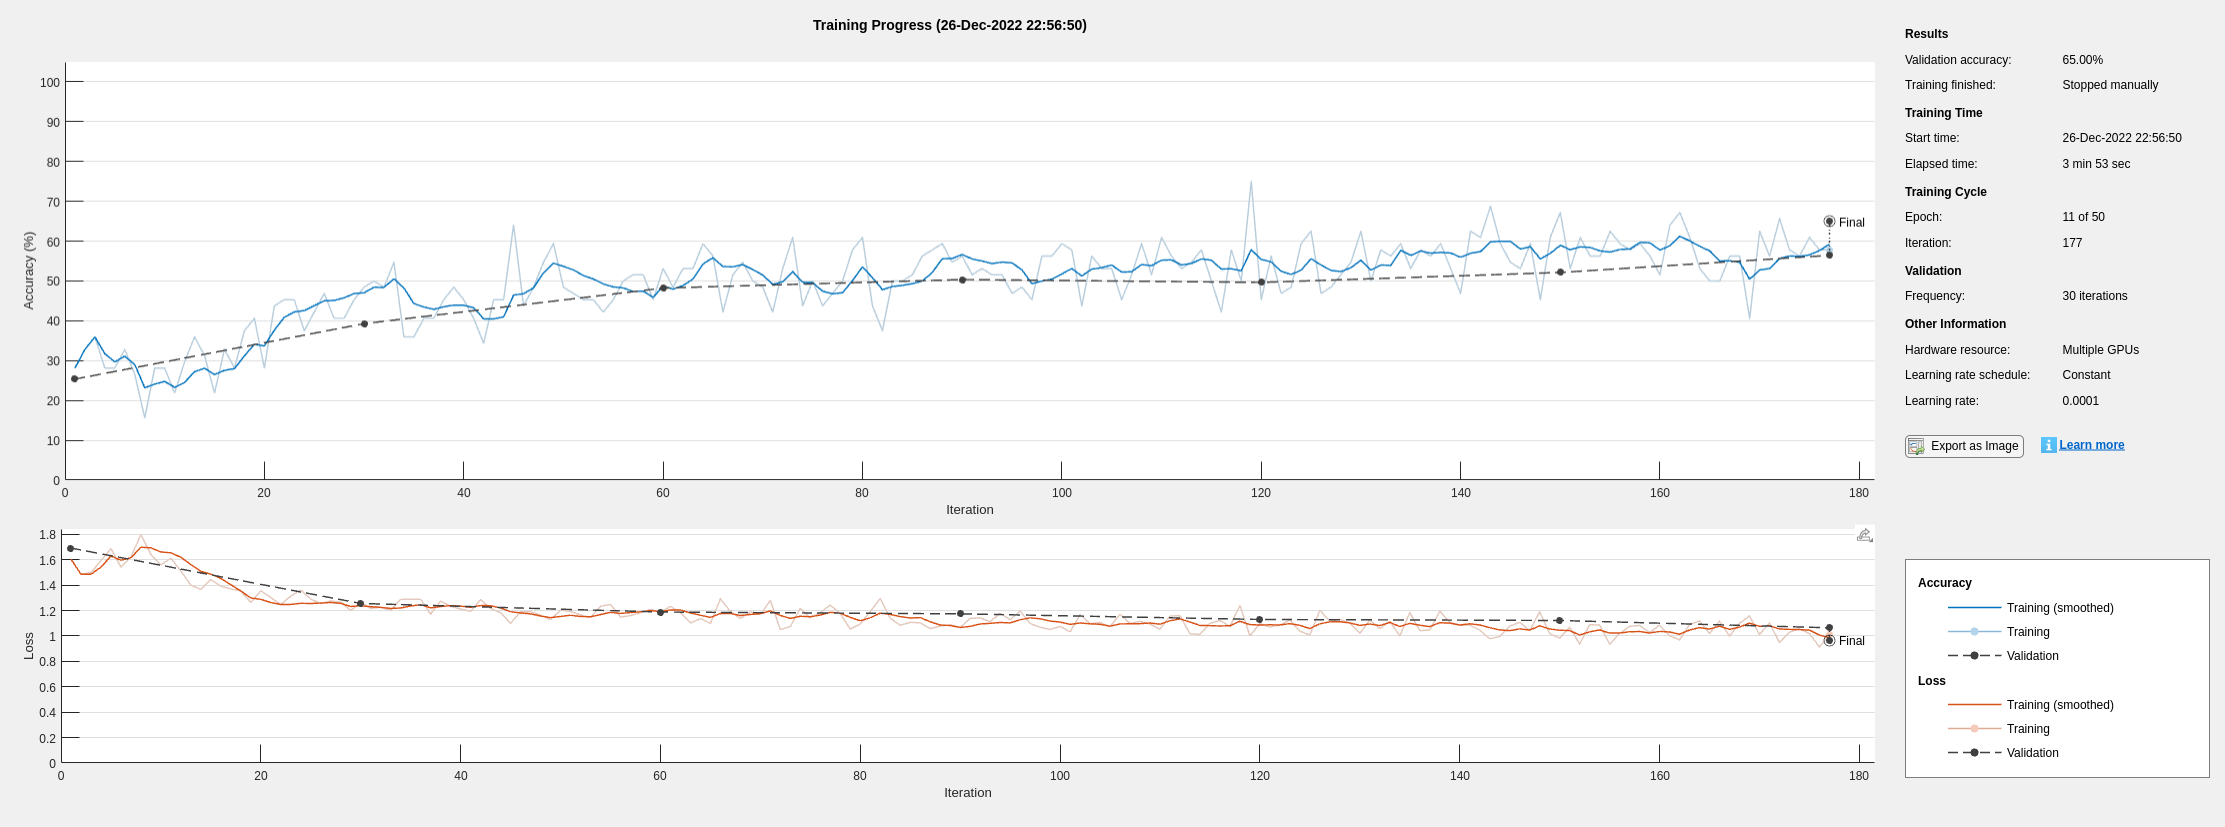

options = trainingOptions('sgdm', ...
    'ExecutionEnvironment','multi-gpu', ...
    'InitialLearnRate',0.0001, ...
    'MaxEpochs',50, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidationM, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'MiniBatchSize',64, ...
    'Plots','training-progress');

%training model
net = trainNetwork(imdsTrainM, lgraph, options);